clear
analysis1=load ("E:\Data\Aurelie\analysis\June2026\invivo_exvivo\119_220919plane0\alignment_analysis.mat");

analysis2=load ("E:\Data\Aurelie\analysis\June2026\invivo_exvivo\119_220923plane0\alignment_analysis.mat");




====== ANALYSE DES PROBABILITÉS ET VÉRIFICATION GROUND TRUTH ======
Précision globale (Accuracy) : 68.55 % (303 / 442 cellules correctes)
Précision sur les couleurs (sans les noires) : 80.16 % (303 / 378 cellules correctes)



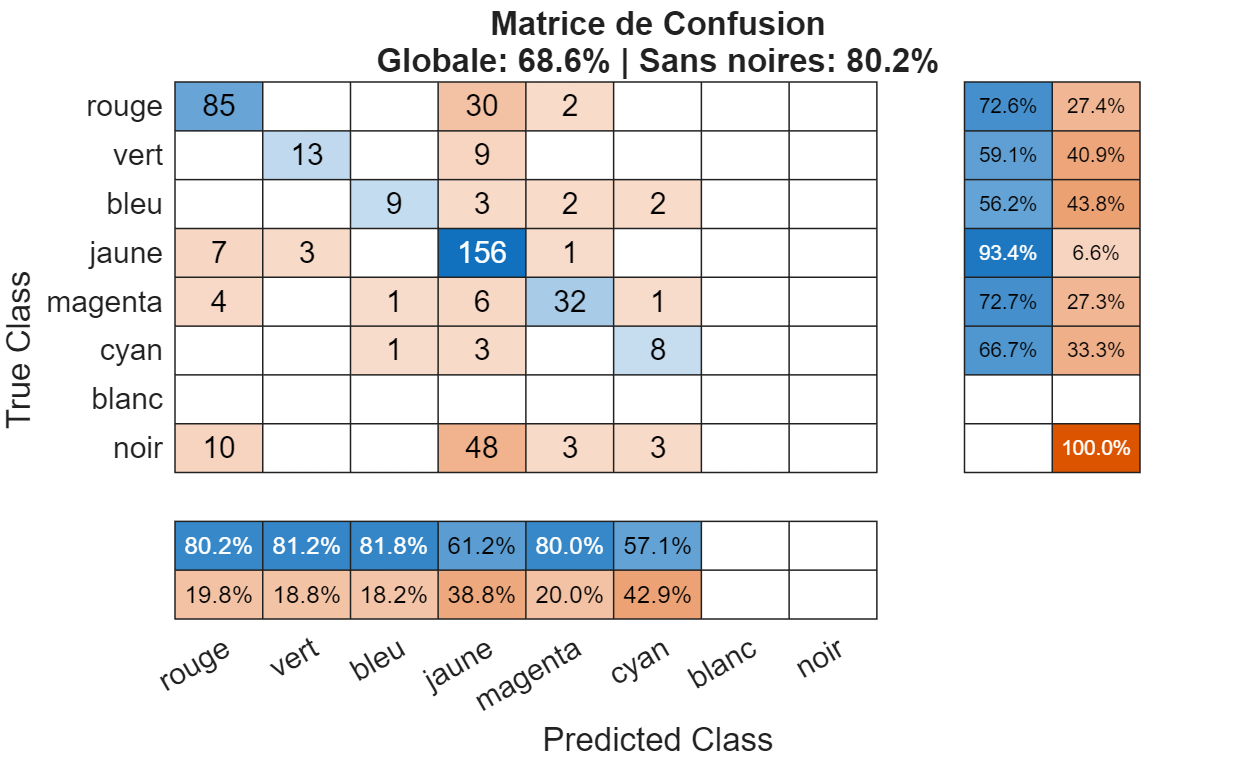

L'algorithme est en désaccord avec la Ground Truth sur 139 cellules.


ATTENTION : cellules où l'algorithme est TRÈS SÛR (>80%) mais contredit la GT.
    47    52    55    65    73    87    91   105   110   131   138   150   156   157   162   168   190   197   198   202   203   212   221   227   238   240   246   250   275   284   285   290   291   293   295   317   322   335   337   344   346   349   358   361   362   366   371   373   375   384   386   389   391   395   406   417   424   425   428   435   437   451   485


====== ACCURACY APRÈS REJET DES CELLULES INCERTAINES (< 50%) ======
Cellules conservées : 426 (16 rejetées sur 442)
Précision globale filtrée : 70.42 % (300 / 426)
Précision sur couleurs filtrées : 81.08 % (300 / 370)



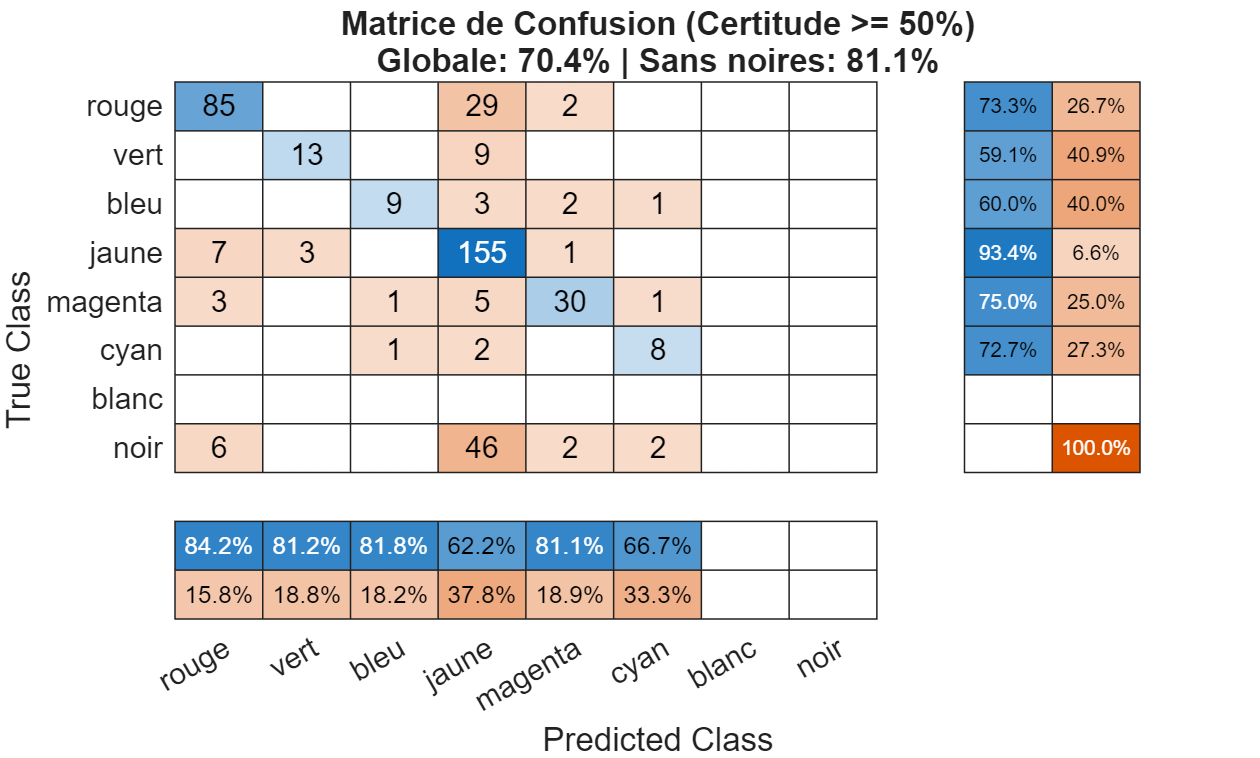

%test modele 1 sur données 1
cell_IDs = analysis1.cell_IDs;
seuil_faible = 0.5;
[certitude_max, scores, accuracy_pct,accuracy_pct_sans_noires, C_matrix,truth_labels] =... 
test_model(analysis1.MdlLin, analysis1.X_raw(cell_IDs, :), analysis1.Ycat_raw(cell_IDs, :),cell_IDs,0,seuil_faible);

accuracy(1,1)=accuracy_pct_sans_noires;



====== ANALYSE DES PROBABILITÉS ET VÉRIFICATION GROUND TRUTH ======
Précision globale (Accuracy) : 63.67 % (170 / 267 cellules correctes)
Précision sur les couleurs (sans les noires) : 75.56 % (170 / 225 cellules correctes)



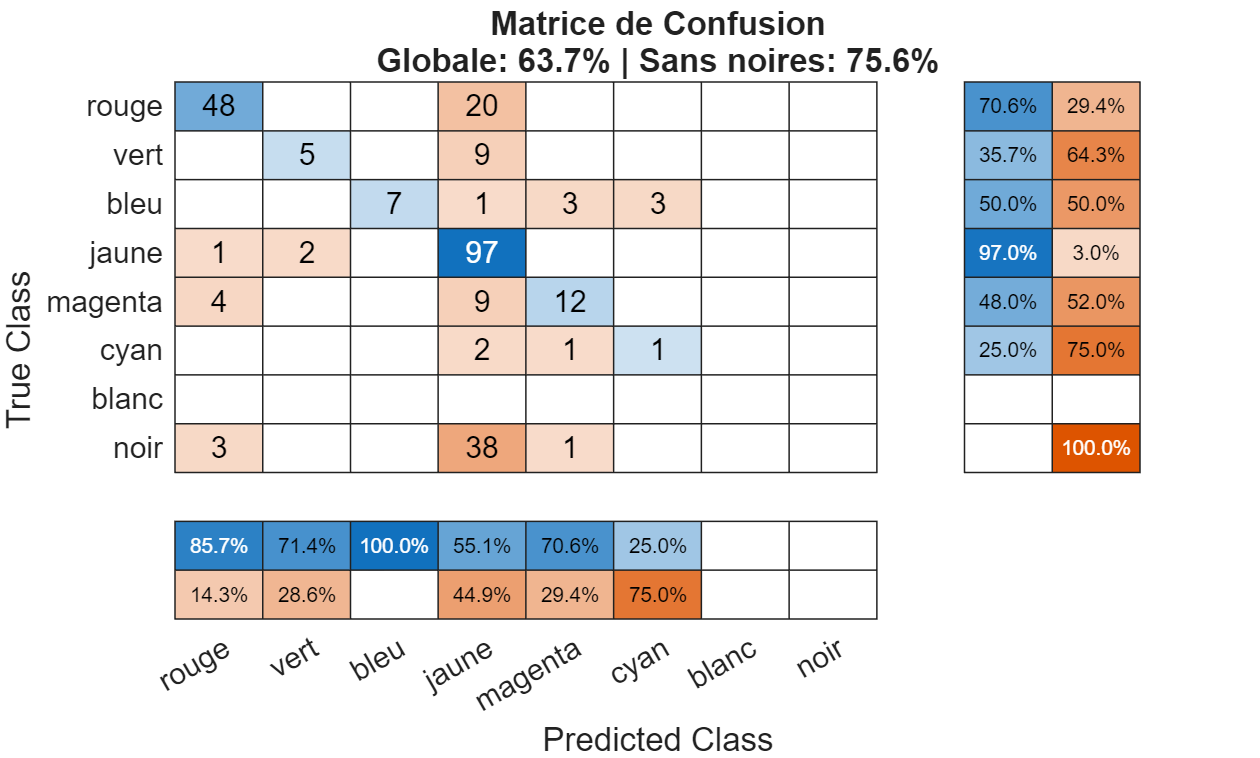

L'algorithme est en désaccord avec la Ground Truth sur 97 cellules.


ATTENTION : cellules où l'algorithme est TRÈS SÛR (>80%) mais contredit la GT.
     1     7    16    30    40    47    69    72    75    78    85    89    90    91    93    97   105   108   109   114   120   125   127   130   134   135   139   145   149   150   154   161   166   185   186   189   196   206   214   224   226   232   233   234   238   246   248   251   263   265   266   267   273   276   280   283   284   288   297   305


====== ACCURACY APRÈS REJET DES CELLULES INCERTAINES (< 50%) ======
Cellules conservées : 264 (3 rejetées sur 267)
Précision globale filtrée : 64.39 % (170 / 264)
Précision sur couleurs filtrées : 76.58 % (170 / 222)



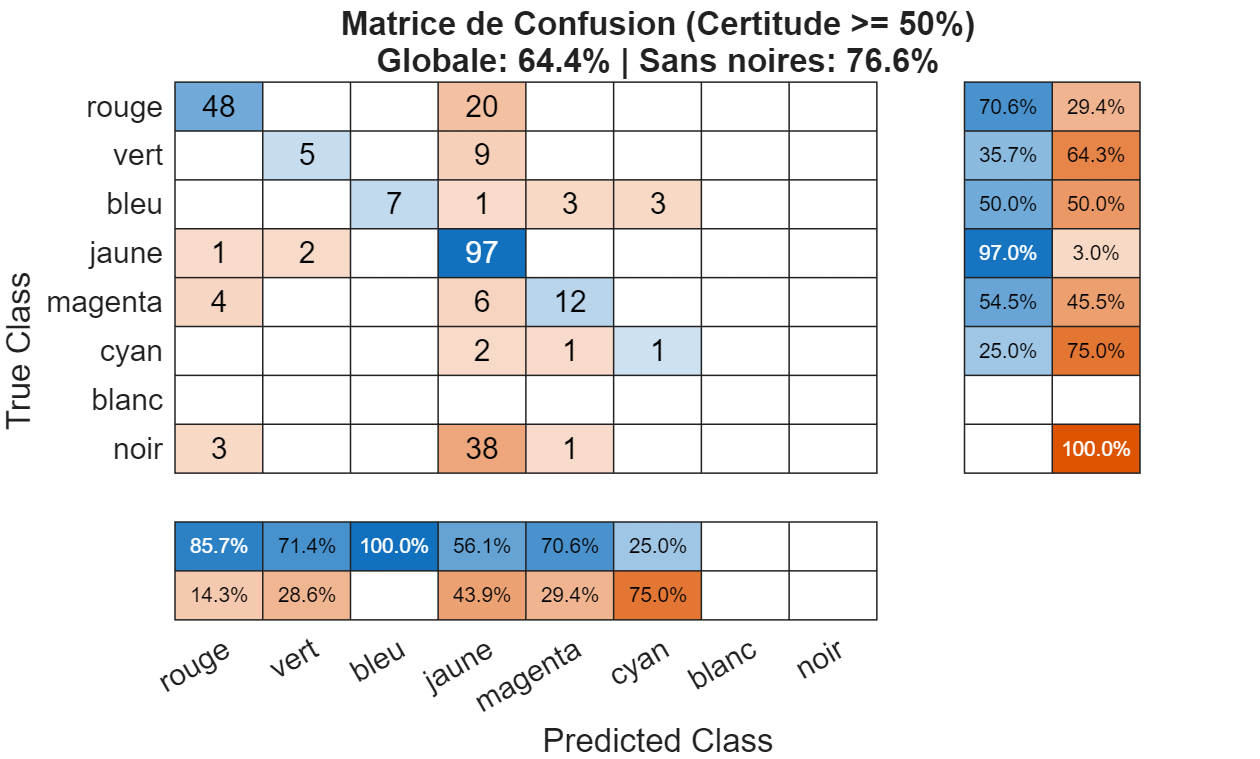

%test modele 1 sur données 2
cell_IDs = analysis2.cell_IDs;
seuil_faible = 0.5;
[certitude_max, scores, accuracy_pct,accuracy_pct_sans_noires, C_matrix,truth_labels] =... 
test_model(analysis1.MdlLin, analysis2.X_raw(cell_IDs, :), analysis2.Ycat_raw(cell_IDs, :),cell_IDs,0,seuil_faible);

accuracy(1,2)=accuracy_pct_sans_noires;



====== ANALYSE DES PROBABILITÉS ET VÉRIFICATION GROUND TRUTH ======
Précision globale (Accuracy) : 65.16 % (288 / 442 cellules correctes)
Précision sur les couleurs (sans les noires) : 76.19 % (288 / 378 cellules correctes)



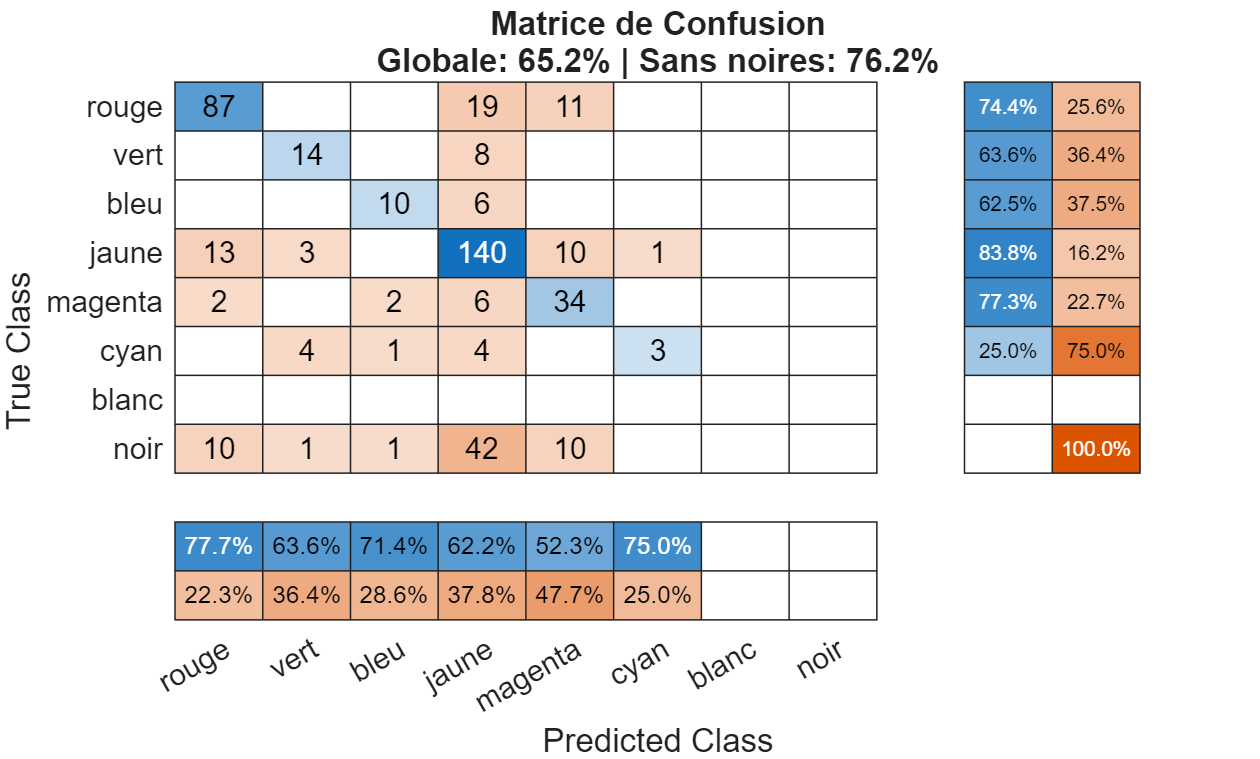

L'algorithme est en désaccord avec la Ground Truth sur 154 cellules.


ATTENTION : cellules où l'algorithme est TRÈS SÛR (>80%) mais contredit la GT.
     2    26    34    47    55    73    76    87    89    91   105   150   151   157   162   167   169   175   198   201   202   203   212   221   232   240   246   250   275   284   285   290   295   317   322   337   342   353   361   366   373   375   381   388   391   393   394   395   406   410   415   417   428   435   437   453   477   485   488


====== ACCURACY APRÈS REJET DES CELLULES INCERTAINES (< 50%) ======
Cellules conservées : 423 (19 rejetées sur 442)
Précision globale filtrée : 66.90 % (283 / 423)
Précision sur couleurs filtrées : 77.32 % (283 / 366)



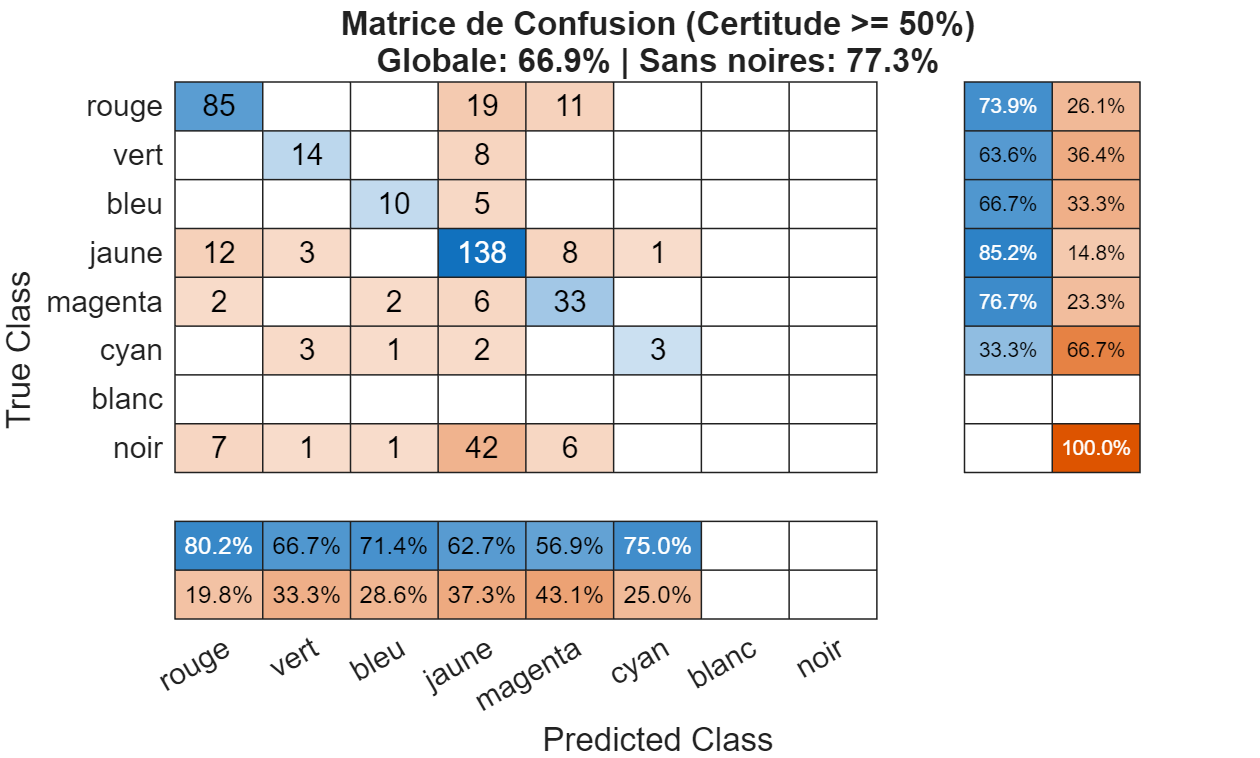

%test modele 2 sur données 1 
cell_IDs = analysis1.cell_IDs;
seuil_faible = 0.5;
[certitude_max, scores, accuracy_pct,accuracy_pct_sans_noires, C_matrix,truth_labels] =... 
test_model(analysis2.MdlLin, analysis1.X_raw(cell_IDs, :), analysis1.Ycat_raw(cell_IDs, :),cell_IDs,0,seuil_faible);

accuracy(2,1)=accuracy_pct_sans_noires;



====== ANALYSE DES PROBABILITÉS ET VÉRIFICATION GROUND TRUTH ======
Précision globale (Accuracy) : 68.16 % (182 / 267 cellules correctes)
Précision sur les couleurs (sans les noires) : 80.89 % (182 / 225 cellules correctes)



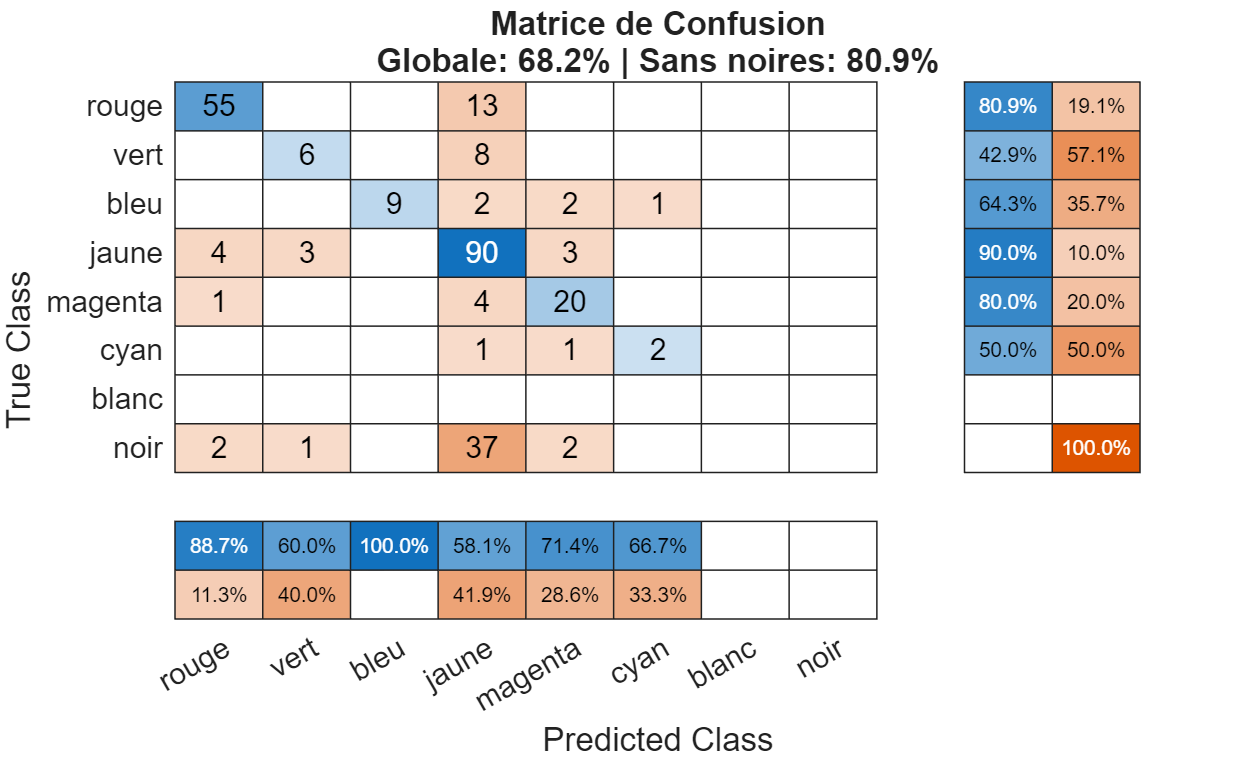

L'algorithme est en désaccord avec la Ground Truth sur 85 cellules.


ATTENTION : cellules où l'algorithme est TRÈS SÛR (>80%) mais contredit la GT.
    13    30    47    60    64    66    72    75    78    85    90    91    93    97   109   114   123   130   134   149   150   161   162   166   181   185   186   206   226   230   232   233   234   238   246   248   251   260   263   265   266   267   276   280   283   297   305


====== ACCURACY APRÈS REJET DES CELLULES INCERTAINES (< 50%) ======
Cellules conservées : 263 (4 rejetées sur 267)
Précision globale filtrée : 68.82 % (181 / 263)
Précision sur couleurs filtrées : 81.53 % (181 / 222)



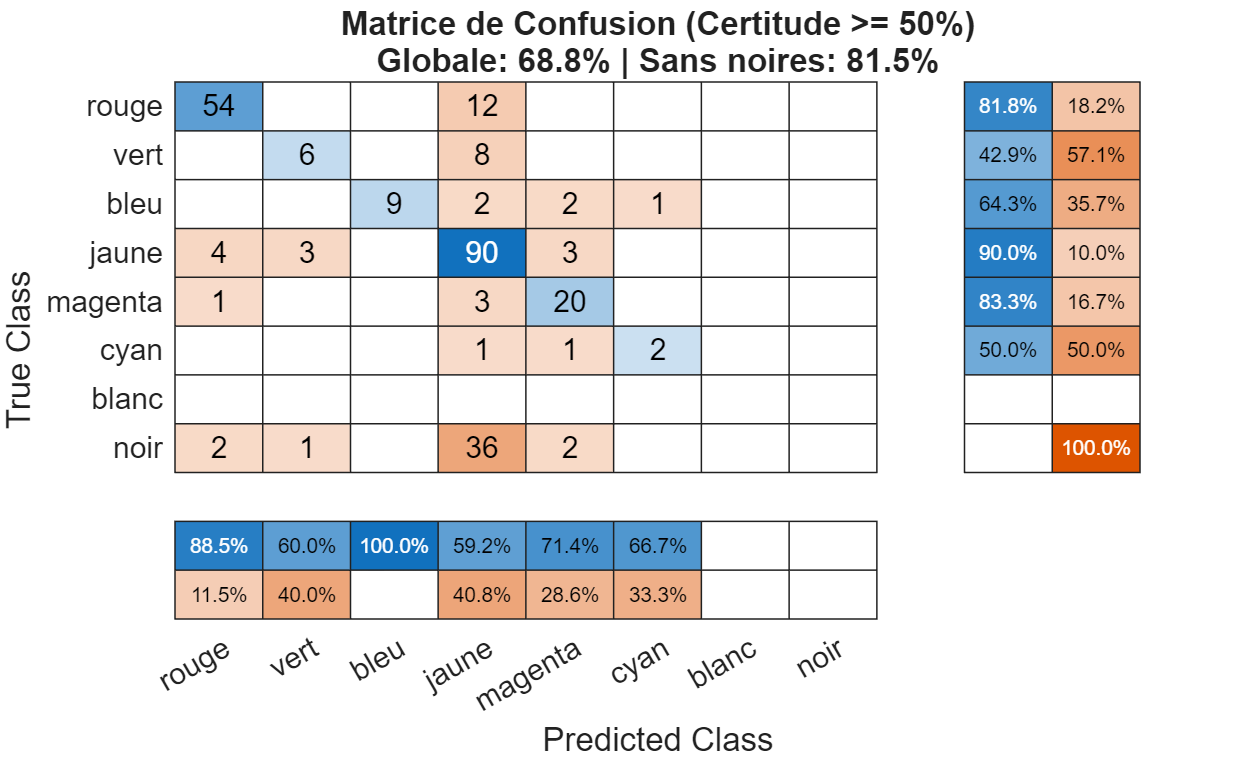

%test modele 2 sur données 1 
cell_IDs = analysis2.cell_IDs;
seuil_faible = 0.5;
[certitude_max, scores, accuracy_pct,accuracy_pct_sans_noires, C_matrix,truth_labels] =... 
test_model(analysis2.MdlLin, analysis2.X_raw(cell_IDs, :), analysis2.Ycat_raw(cell_IDs, :),cell_IDs,0,seuil_faible);

accuracy(2,2)=accuracy_pct_sans_noires;

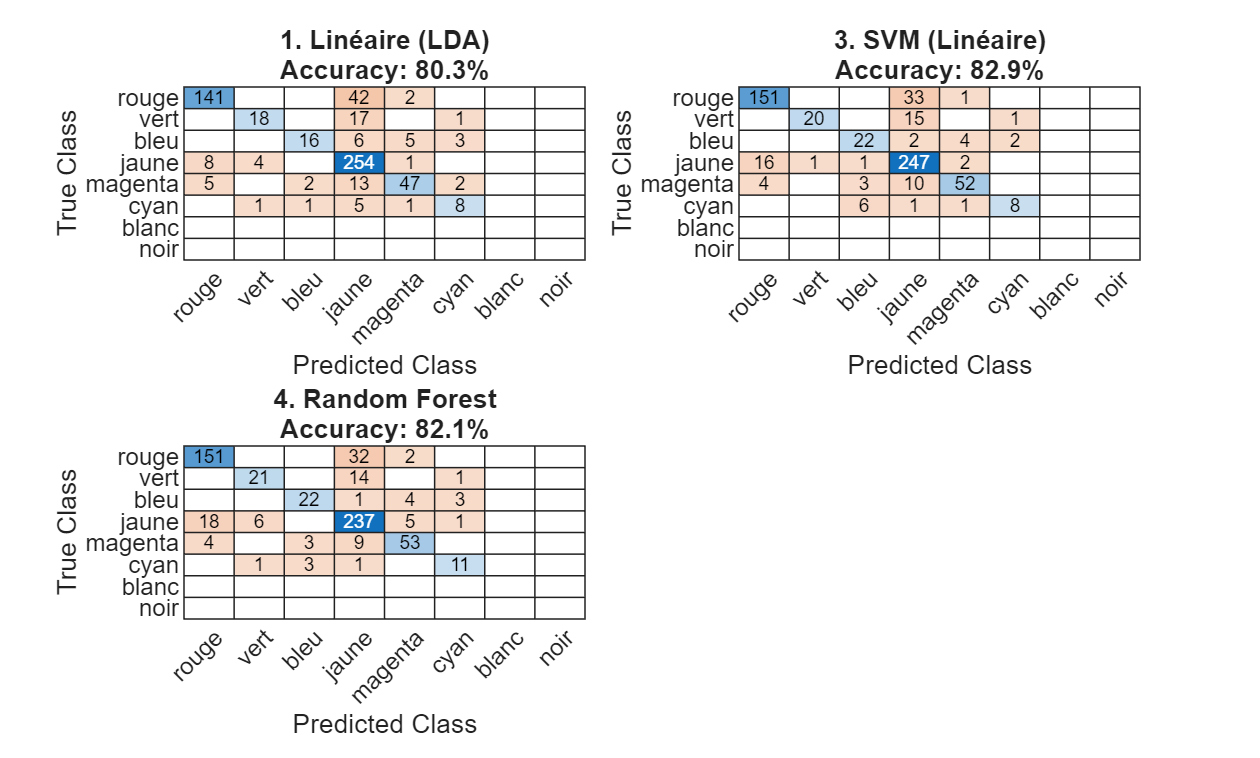


====== RÉSULTATS DE LA CROSS-VALIDATION ======
1. Linéaire (LDA)       : 80.27 %
3. SVM Multi-classes    : 82.92 %
4. Random Forest        : 82.09 %


%construction dataset groupé analysis 1 and 2

x_grouped = [analysis1.X_raw(analysis1.cell_IDs, :) ; analysis2.X_raw(analysis2.cell_IDs, :) ];
% y_grouped = [analysis1.Ycat_raw(analysis1.cell_IDs, :) ; analysis2.Ycat_raw(analysis2.cell_IDs, :) ];
% analysis1.colorcell_exvivo
colorcell_grouped = [analysis1.colorcell_exvivo(analysis1.cell_IDs) ;analysis2.colorcell_exvivo(analysis2.cell_IDs)]; 
% roi_red_grouped = [analysis1.roi_red_corrected(analysis1.cell_IDs) ;analysis2.colorcell_exvivo(analysis2.cell_IDs)]; 
% roi_green_grouped
% roi_blue_grouped
% roi_ca_grouped
[MdlLin_grouped, MdlSVM, MdlRF,X,Ycat, X_raw,Ycat_raw, cell_IDs] = prediction_color(colorcell_grouped,x_grouped(:,1),x_grouped(:,2),x_grouped(:,3),x_grouped(:,4));



====== ANALYSE DES PROBABILITÉS ET VÉRIFICATION GROUND TRUTH ======
Précision globale (Accuracy) : 67.04 % (179 / 267 cellules correctes)
Précision sur les couleurs (sans les noires) : 79.56 % (179 / 225 cellules correctes)



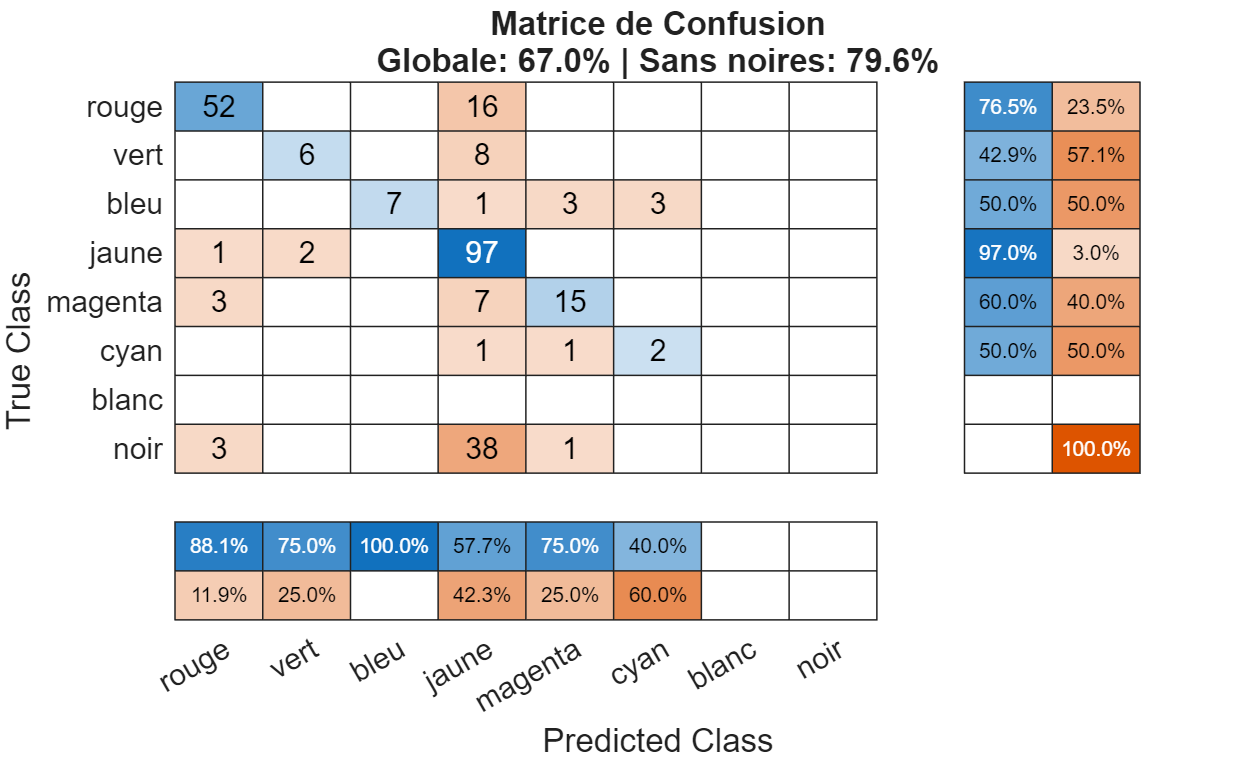

L'algorithme est en désaccord avec la Ground Truth sur 88 cellules.


ATTENTION : cellules où l'algorithme est TRÈS SÛR (>80%) mais contredit la GT.
    16    30    40    47    66    72    75    78    85    89    90    91    93    97   105   109   114   127   130   134   135   139   149   150   154   161   166   185   186   196   206   214   224   226   230   232   233   234   238   246   248   251   260   263   265   266   267   273   276   280   283   284   297   305


====== ACCURACY APRÈS REJET DES CELLULES INCERTAINES (< 50%) ======
Cellules conservées : 260 (7 rejetées sur 267)
Précision globale filtrée : 67.69 % (176 / 260)
Précision sur couleurs filtrées : 80.37 % (176 / 219)



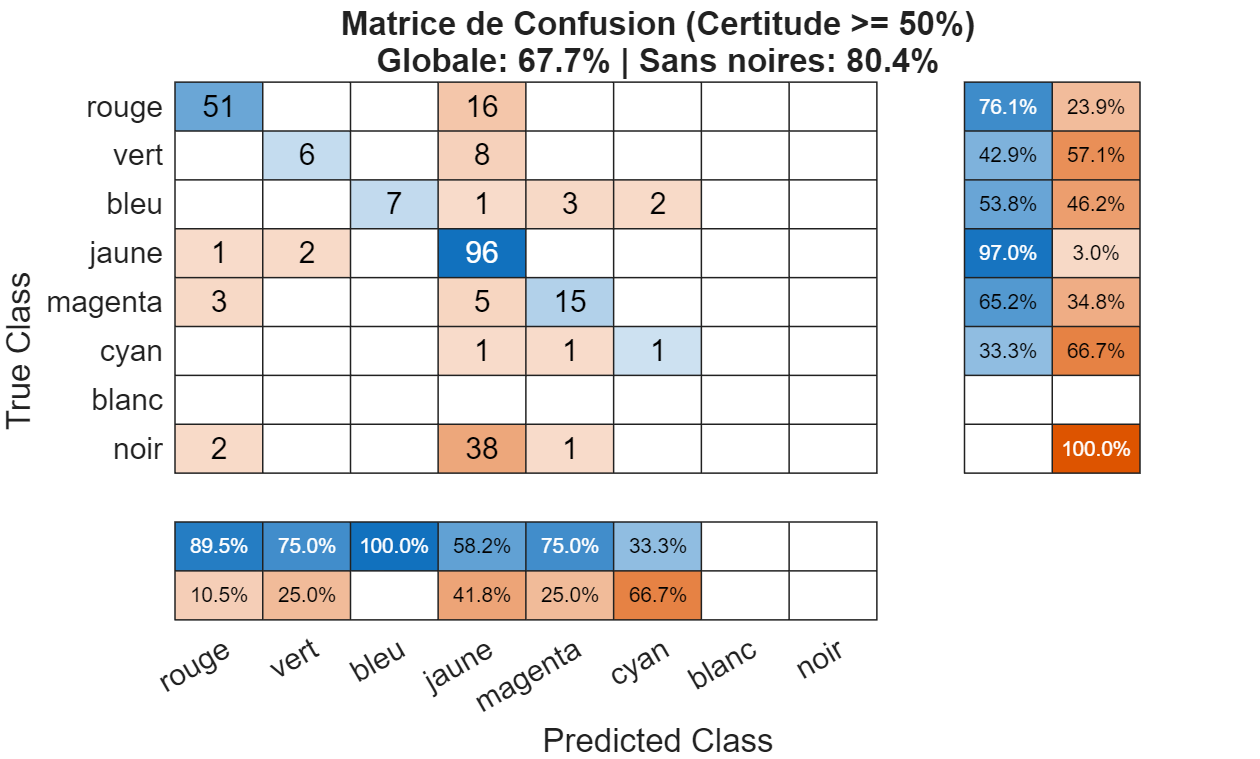

%test modele grouped sur données 2
cell_IDs = analysis2.cell_IDs;
seuil_faible = 0.5;
[certitude_max, scores, accuracy_pct,accuracy_pct_sans_noires, C_matrix,truth_labels] =... 
test_model(MdlLin_grouped, analysis2.X_raw(cell_IDs, :), analysis2.Ycat_raw(cell_IDs, :),cell_IDs,0,seuil_faible);

accuracy(3,2)=accuracy_pct_sans_noires;



====== ANALYSE DES PROBABILITÉS ET VÉRIFICATION GROUND TRUTH ======
Précision globale (Accuracy) : 70.81 % (313 / 442 cellules correctes)
Précision sur les couleurs (sans les noires) : 82.80 % (313 / 378 cellules correctes)



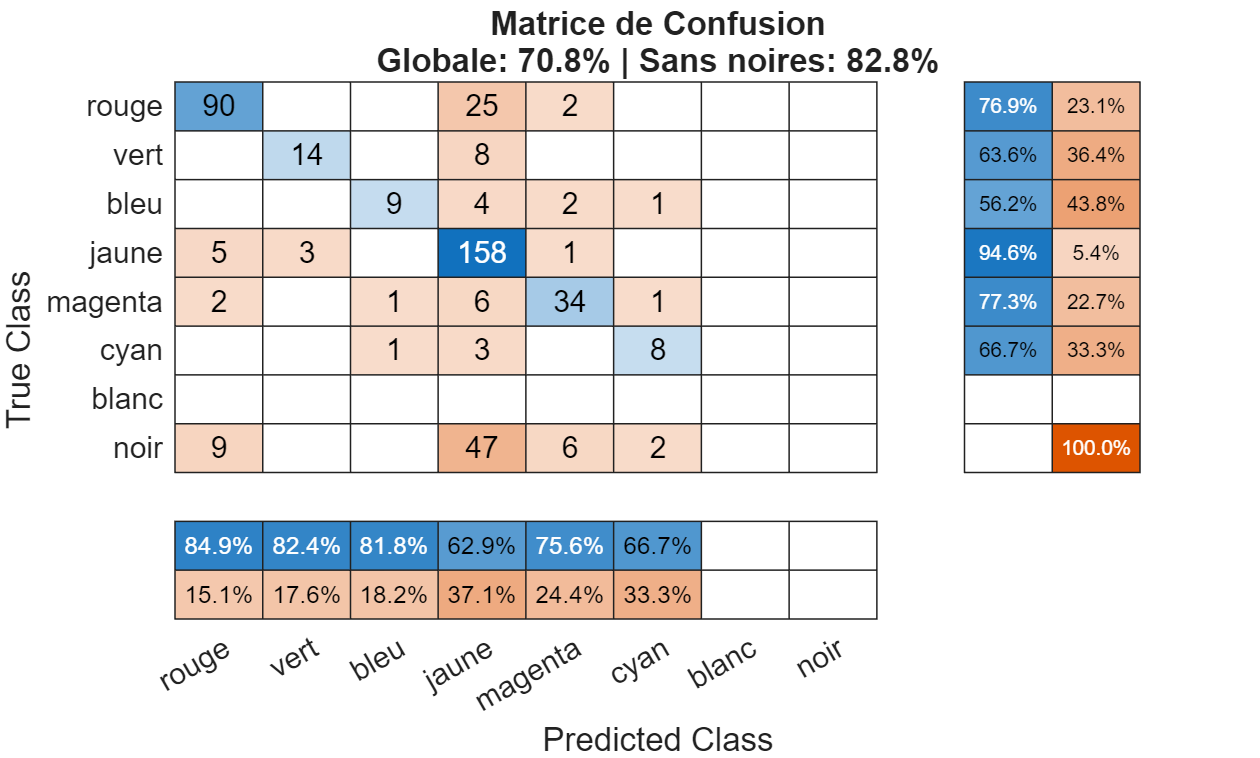

L'algorithme est en désaccord avec la Ground Truth sur 129 cellules.


ATTENTION : cellules où l'algorithme est TRÈS SÛR (>80%) mais contredit la GT.
    47    52    55    73    87    89    91   105   138   150   156   157   162   190   197   198   202   203   212   221   227   238   240   250   275   284   285   290   293   295   317   322   335   337   344   346   358   361   362   366   371   373   375   384   391   395   406   417   424   425   428   435   437   485


====== ACCURACY APRÈS REJET DES CELLULES INCERTAINES (< 50%) ======
Cellules conservées : 425 (17 rejetées sur 442)
Précision globale filtrée : 72.47 % (308 / 425)
Précision sur couleurs filtrées : 83.92 % (308 / 367)



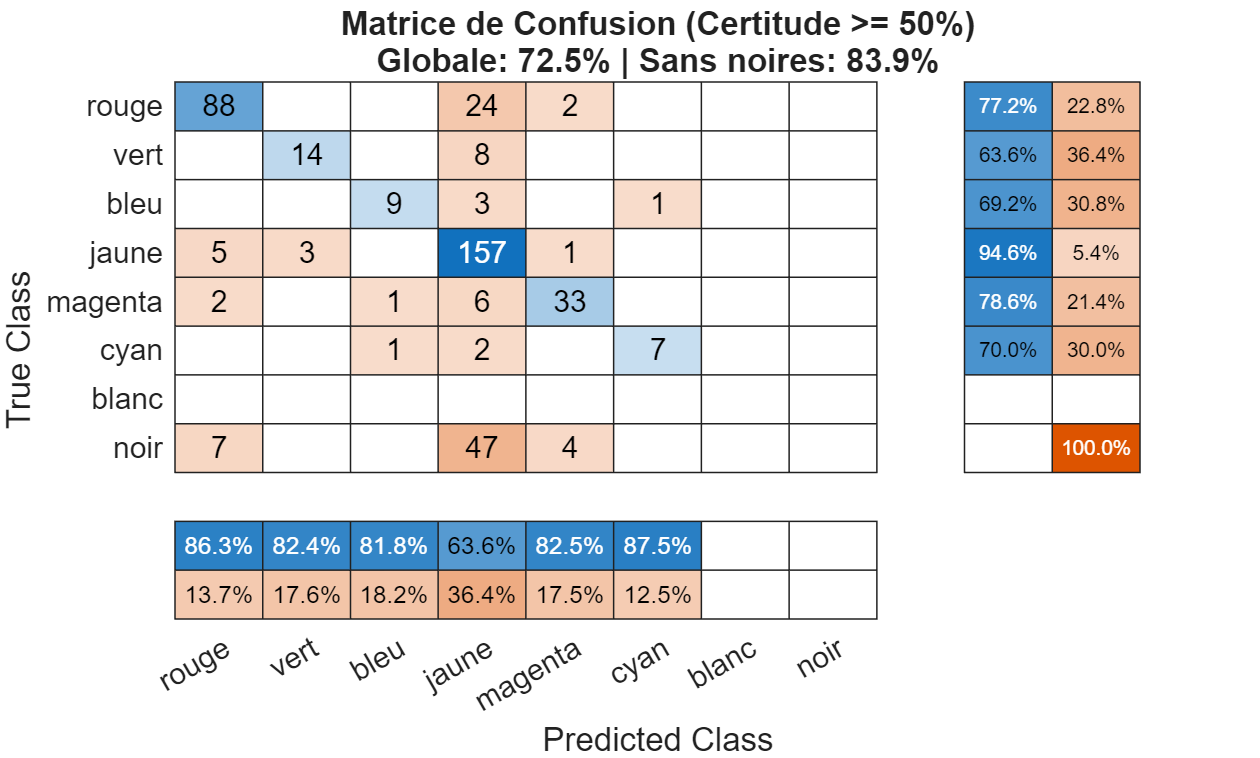

%test modele grouped sur données 1 
cell_IDs = analysis1.cell_IDs;
seuil_faible = 0.5;
[certitude_max, scores, accuracy_pct,accuracy_pct_sans_noires, C_matrix,truth_labels] =... 
test_model(MdlLin_grouped, analysis1.X_raw(cell_IDs, :), analysis1.Ycat_raw(cell_IDs, :),cell_IDs,0,seuil_faible);

accuracy(3,1)=accuracy_pct_sans_noires;



====== ANALYSE DES PROBABILITÉS ET VÉRIFICATION GROUND TRUTH ======
Précision globale (Accuracy) : 81.59 % (492 / 603 cellules correctes)
Précision sur les couleurs (sans les noires) : 81.59 % (492 / 603 cellules correctes)



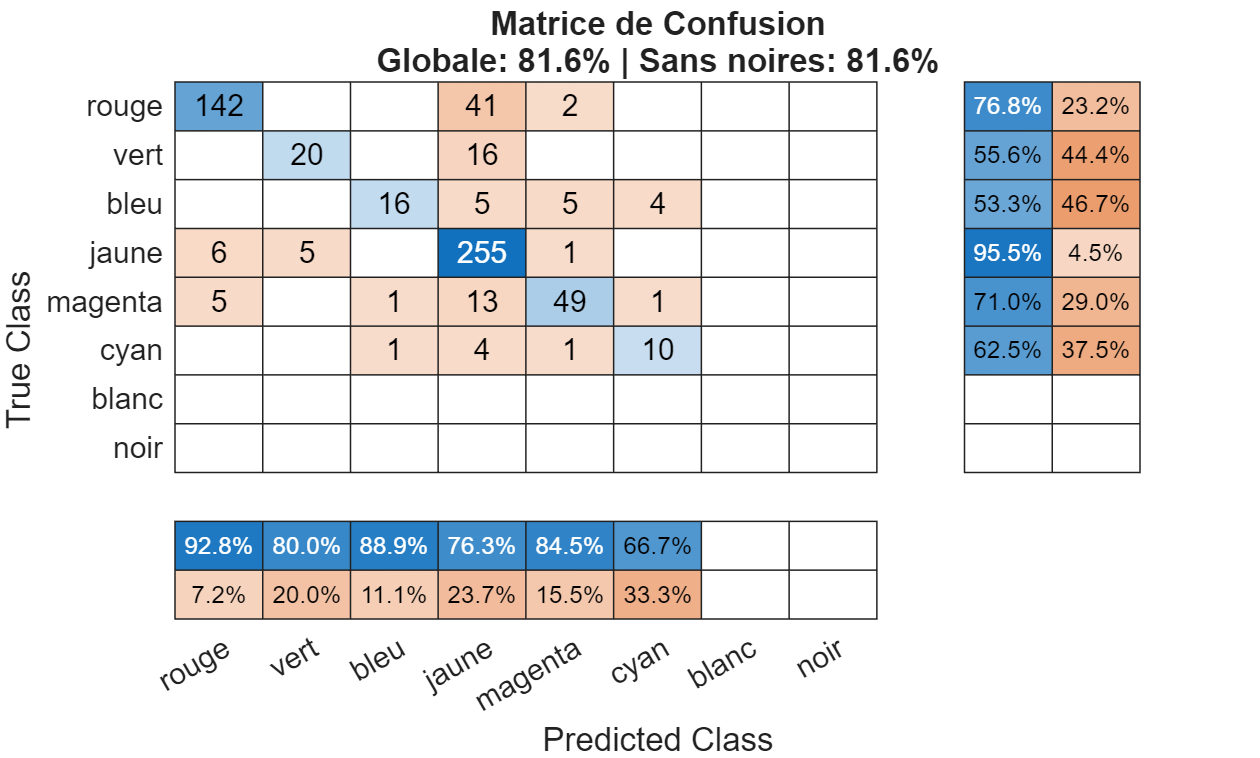

L'algorithme est en désaccord avec la Ground Truth sur 111 cellules.


ATTENTION : cellules où l'algorithme est TRÈS SÛR (>80%) mais contredit la GT.
    45    52    82   122   138   170   176   177   193   199   208   210   219   267   271   297   300   304   317   337   392   406   446   452   455   456   457   468   485   490   494   503   507   547   554   564   573   581   583   586   589   592


====== ACCURACY APRÈS REJET DES CELLULES INCERTAINES (< 50%) ======
Cellules conservées : 586 (17 rejetées sur 603)
Précision globale filtrée : 82.59 % (484 / 586)
Précision sur couleurs filtrées : 82.59 % (484 / 586)



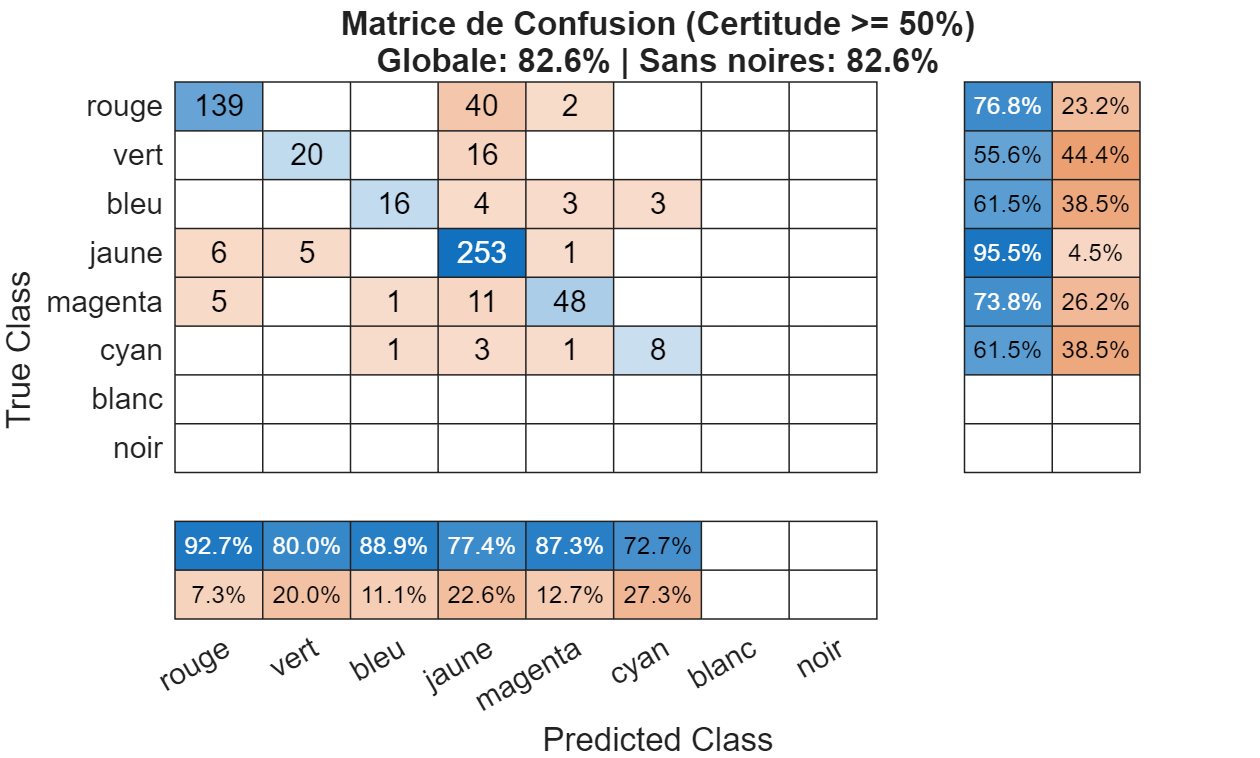

%test modele grouped sur données grouped 

seuil_faible = 0.5;
[certitude_max, scores, accuracy_pct,accuracy_pct_sans_noires, C_matrix,truth_labels] =... 
test_model(MdlLin_grouped, X,Ycat,1:numel(Ycat),0,seuil_faible);

accuracy(3,3)=accuracy_pct_sans_noires;

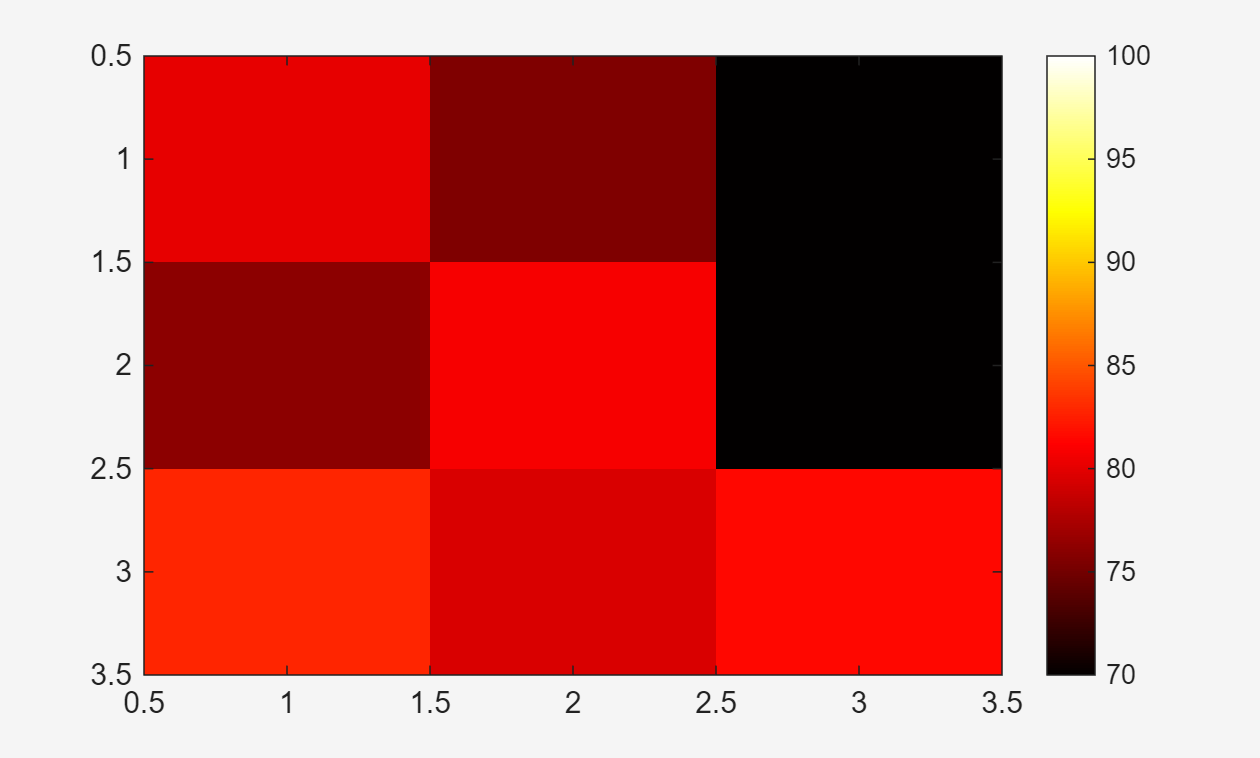

figure(visible='on');
imagesc(accuracy)
colormap ('hot')
colorbar 
clim ([70 100])

% figure(Visible='on');histogram(certitude_max,10)